##                                                      Robótica - Lista de Exercícios 4 parte 2

**                        Nome: **Marcos Carvalho Ferreira                                                                            **Matrícula:** 202010203

import RoboticaBiblioteca.*
printListaManipuladores()

--------------------> Lista de Manipuladores <-----------------------
1 - Manipulador Cartesiano: PPP
   1.1 - Manipulador Pórtico: cartesianos, mas com base em suportes
2 - Manipulador Cilíndrico: RPP
3 - Manipulador Articulados/Antropomórficos: RRR
4 - Manipulador Esféricos/Polares: RRP
5 - Manipulador SCARA: RRP, diferente do esférico, tem três eixos z0,
                       z1 e z2 todos verticais e paralelos


**Questão 6**

Considerando a frame apresentada na imagem abaixo, represente a nova posição e orientação da mesma a partir dos seguintes movimentos.

a) Translação em x igual a 3un.

b) “roll” corrente de 45º

c) “yaw” corrente de 90º

d) “pitch” corrente de 90º

e) Translação em z fixo igual a -2un

                                                                                    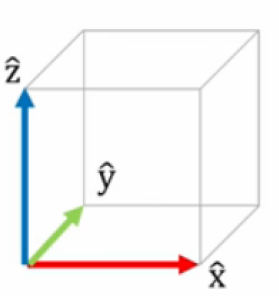

trans(0,0,-2)*trans(3,0,0)*rot('n',45)*rot('a',90)*rot('o',90)

ans =          0   -1.0000         0    3.0000
    0.7071         0    0.7071         0
   -0.7071         0    0.7071   -2.0000
         0         0         0    1.0000


%calculo da p1 prática 1-a
H16=rot('z',45)*rot('a',90)*trans(0,4,0)*trans(0,0,2)*rot('y',30)

H16 =    -0.6124   -0.7071   -0.3536   -2.8284
    0.6124   -0.7071    0.3536   -2.8284
   -0.5000         0    0.8660    2.0000
         0         0         0    1.0000


%questão b
novorefC=H16*trans(2,5,6)

novorefC =    -0.6124   -0.7071   -0.3536   -9.7100
    0.6124   -0.7071    0.3536   -3.0179
   -0.5000         0    0.8660    6.1962
         0         0         0    1.0000


**Questão 7**

R = rotZYZ(180/2,0,180/4)

R =    -0.7071   -0.7071         0         0
    0.7071   -0.7071         0         0
         0         0    1.0000         0
         0         0         0    1.0000


**Questão 8**

**a) **Considere que no manipulador da Figura abaixo, foi anexado um punho esférico do tipo RAG. Determine a cinemática de posição e orientação para o referido manipulador considerando que a distancia do punho ao MP é igual a 92mm e que a matriz de transformação homogênea que representa a transformação total para um determinado ponto é igual a:

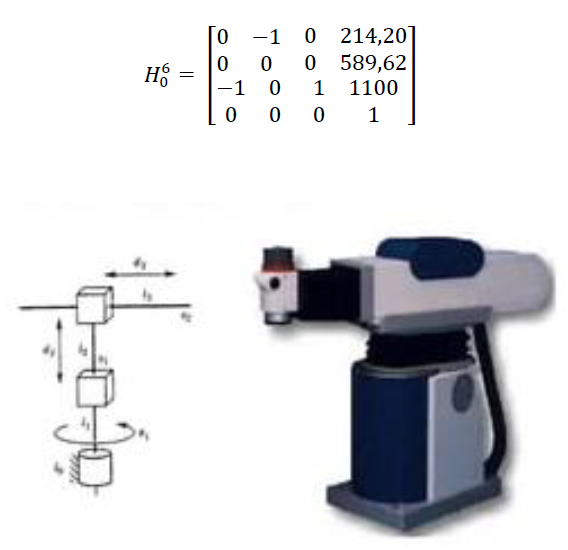

Determinar a cinemática de posição:


$$p_c =d_0^6 -d_6 \cdot R_0^6 \cdot k$$


pc = [214.20; 589.62; 1100] - 92*[0 -1 0; 0 0 1; -1 0 0]*[0; 0; 1]

pc = 1.0e+03 *

    0.2142
    0.4976
    1.1000


pc = [-9.7100;-3.0179;6.1962]-[-0.6124 -0.7071 -0.3536; 0.6124 -0.7071 0.3536; -0.5000 0 0.8660]*[1;2;3]

pc =    -6.6226
   -3.2769
    4.0982


[r, alpha, l] = movimentosTcil(-9.7100,-3.0179,6.1962);

r = 10.168177 | alpha = -162.734583 | L = 6.196200


[r, alpha, l] = movimentosTcil(214.20,589.62,1008);

r = 627.322393 | alpha = 70.034685 | L = 1008.000000


Determinar a cinemática de orientação:

R06 = R03 * R36

(R03)^-1 * R06 = (R03)^-1 * R03 * R36

R36 = (R03)^-1 * R06

refH12= Tcil(10,20,30)

refH12 =     0.9397   -0.3420         0    9.3969
    0.3420    0.9397         0    3.4202
         0         0    1.0000   30.0000
         0         0         0    1.0000


%T03 = Tcil(3.999962,-135,2)
R03 = [0.9397 -0.3420 0;
       0.3420 0.9397 0;
       0 0 1];
R06 = [-0.6124 -0.7071 -0.3536; 0.6124 -0.7071 0.3536; -0.5000 0 0.8660];
R36 = (R03)^-1 * R06

R36 =    -0.3660   -0.9063   -0.2113
    0.7849   -0.4226    0.4532
   -0.5000         0    0.8660


T36 = [R36, zeros(3,1);
       zeros(1,3), 1];
[thetaN, thetaO, thetaA] = angsRAG(T36);

ThetaN = 0.000000 | ThetaO = 29.998884 | ThetaA = 115.001229


**b)** Faça o mesmo procedimento para o manipulador abaixo, considerando a mesma matriz de transformação homogênea 𝐻06, e um punho esférico do tipo Euler.

                                                                                                    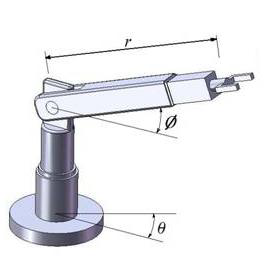

Determinar a cinemática de posição:


$$p_c =d_0^6 -d_6 \cdot R_0^6 \cdot k$$


pc = [573; 0; 440] - [0 0 1; 0 -1 0; 1 0 0]*[0; 0; 1]

pc =    572
     0
   440


[r, beta, gamma] = movimentosTesf(573,0,440);

r = 722.446538 | beta = 52.479763 | gamma = 0.000000


Determinar a cinemática de orientação:

R06 = R03 * R36

(R03)^-1 * R06 = (R03)^-1 * R03 * R36

R36 = (R03)^-1 * R06

T03 = Tesf(r,beta,gamma)

T03 =     0.6090         0    0.7931  573.0000
         0    1.0000         0         0
   -0.7931         0    0.6090  440.0000
         0         0         0    1.0000


R03 = T03(1:3,1:3);
R06 = [0 0 1; 0 -1 0; 1 0 0];
R36 = (R03)^-1 * R06

R36 =    -0.7931         0    0.6090
         0   -1.0000         0
    0.6090         0    0.7931


T36 = [R36, zeros(3,1);
       zeros(1,3), 1];
[theta, phi_plus_psi] = angsEuler(T36);

phi = 0.000000 | theta = 37.520237 | psi = 180.000000


**Questão 9**

Referenciais descrevendo a base de um robô manipulador e um objeto são dados relativos referente ao Universo.

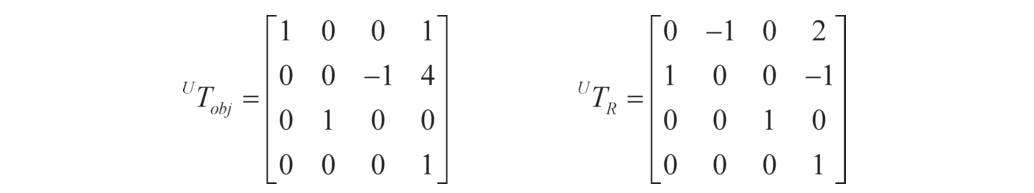

                                                    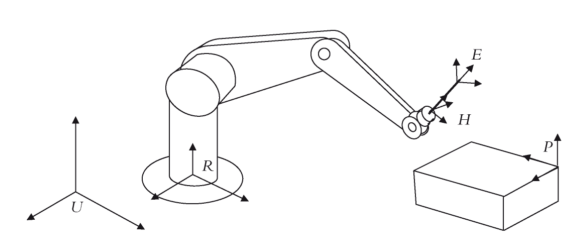

**a) **Encontre a transformação 𝑅𝑇𝐻 da configuração do manipulador, se a mão do robô deve ser colocada no objeto.

H = Obj 

TUObj = TUR*TRH --> (TUR)^-1*TUObj = (TUR)^-1*TUR*TRH --> TRH = (TUR)^-1*TUObj

TUObj = [1 0 0 1;
         0 0 -1 4;
         0 1 0 0;
         0 0 0 1];
TUR = [0 -1 0 2;
       1 0 0 -1;
       0 0 1 0;
       0 0 0 1];
TRH = (TUR^-1)*TUObj

TRH =      0     0    -1     5
    -1     0     0     1
     0     1     0     0
     0     0     0     1


**b) **A partir do resultado obtido em a, pode afirmar que este robô pode ser classificado como um manipulador esférico?

syms r beta gamma;
Tesf(r,beta,gamma)

$$ans = \left(\begin{array}{cccc} \cos\left(\beta \right)\,\cos\left(\gamma \right) & -\sin\left(\gamma \right) & \cos\left(\gamma \right)\,\sin\left(\beta \right) & r\,\cos\left(\gamma \right)\,\sin\left(\beta \right)\\ \cos\left(\beta \right)\,\sin\left(\gamma \right) & \cos\left(\gamma \right) & \sin\left(\beta \right)\,\sin\left(\gamma \right) & r\,\sin\left(\beta \right)\,\sin\left(\gamma \right)\\ -\sin\left(\beta \right) & 0 & \cos\left(\beta \right) & r\,\cos\left(\beta \right)\\ 0 & 0 & 0 & 1 \end{array}\right)$$

Não pode ser considerado um manipulador esférico pois r32 vale 1, na matriz transformação do manipulador esférico r32 deve valer 0

**c)** Supondo que o robô em questão possui coordenadas cartesianas Euler, determine os parâmetros da cinemática direta

Determinar a cinemática de posição:

[Px, Py, Pz] = movimentosTcart(5,1,0);

Px = 5.000000 | Py = 1.000000 | Pz = 0.000000


Determinar a cinemática de orientação:

[phi, theta, psi] = angsEuler(TRH);

phi = 180.000000 | theta = 90.000000 | psi = 90.000000


**Questão 10**

Suponha que um robô móvel montado no braço esteja se movendo em uma sala e queira pegar um objeto frame {e} com seu efetuador final com a estrutura anexada frame {c}:

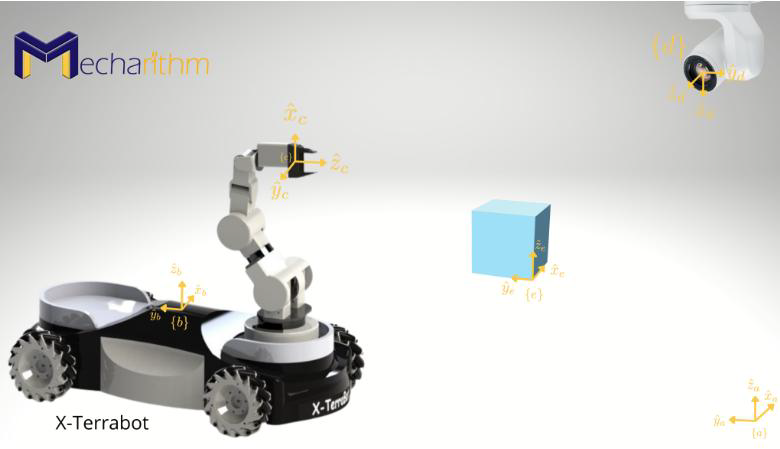

Uma câmera é fixada no teto e, com base em suas medições, é conhecida a configuração das frames presas à plataforma com rodas {b} e a frame do objeto {e} em relação a frame da câmera {d}:

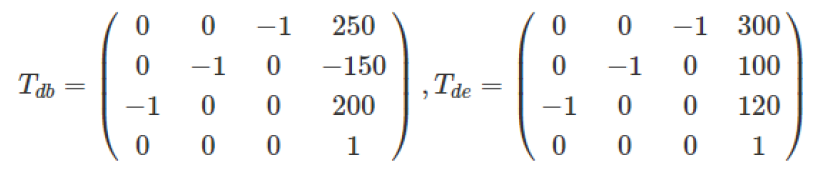

Além disso, usando as medidas do ângulo da articulação do braço, T bc também é conhecido:

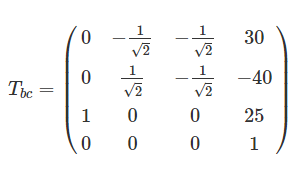

A configuração da frame da câmera {d} em relação a frame do quadro fixo {a} é conhecida antecipadamente:

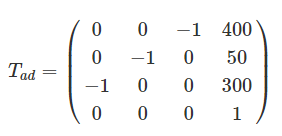

Determine o movimento que deve ser feito para mover o braço do robô para pegar o objeto, 𝑇𝑐𝑒

Tdb = [0 0 -1 250;
       0 -1 0 -150;
       -1 0 0 200;
       0 0 0 1];

Tde = [0 0 -1 300;
       0 -1 0 100;
       -1 0 0 120;
       0 0 0 1];

Tbc = [0 -1/sqrt(2) -1/sqrt(2) 30;
       0 1/sqrt(2) -1/sqrt(2) -40;
       1 0 0 25;
       0 0 0 1];

Tad = [0 0 -1 400;
       0 -1 0 50;
       -1 0 0 300;
       0 0 0 1];

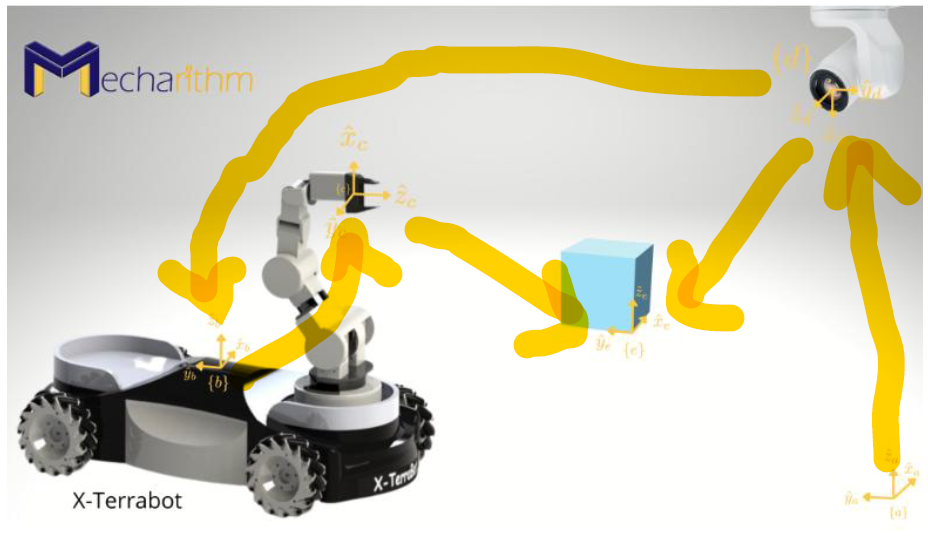

Tae = Tad * Tdb * Tbc *Tce  -->  (Tbc)^-1 * (Tdb)^-1 * (Tad)^-1 * Tae = (Tbc)^-1 * (Tdb)^-1 * (Tad)^-1 * Tad * Tdb * Tbc * Tce

Tce = (Tbc)^-1*(Tdb)^-1*(Tad)^-1*(Tae)

Tae = Tad*Tde

Tce = (Tbc)^-1*(Tdb)^-1*(Tad)^-1***(Tad)*(Tde)**

Tce = (Tbc)^-1(Tdb)^-1*(Tde)

Tce = Tbc^-1 * Tdb^-1 * Tde

Tce =          0         0    1.0000  -75.0000
   -0.7071    0.7071         0 -183.8478
   -0.7071   -0.7071         0  113.1371
         0         0         0    1.0000
